## **Front View **

- Plate 1,3,4

- Crops out the region of the plate

**Task 1 - Preprocessing: Detecting & Extracting Car Number Plate Area**

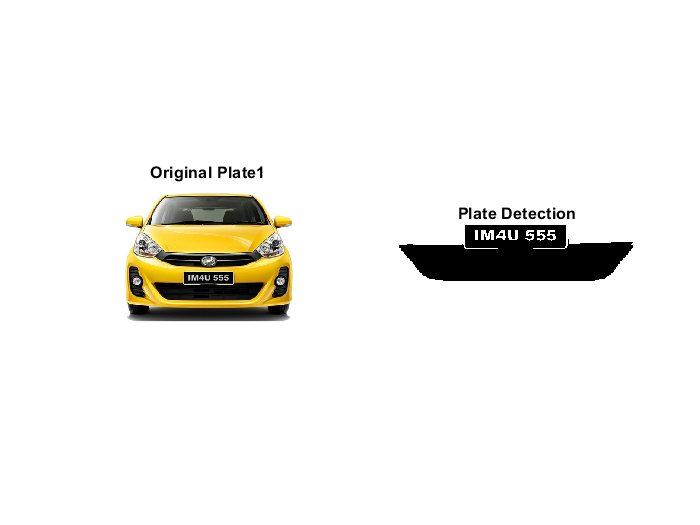

I = imread('C:\Users\issab\Documents\aMonash Units\Y3S1\aFIT3081 Image Processing\Assignment1\Car number plate images\Plate4.jpg');    % Read image
Igray = rgb2gray(I);            % Convert rgb image to grayscale
Ibin = imbinarize(Igray);       % Convert grayscale to binary image
Igray = medfilt2(Igray, [5 5]); % Perform median filtering with 5x5 neighbourhood

% Dilate grayscale image (remove unwanted noise etc...)
SE = strel('disk', 6);  
A = imdilate(Igray, SE);
B = imbinarize(A);

% Edge detection using Prewitt
C = edge(A, 'prewitt');

% Vertical and Horizontal dilation to retrieve lost linear gaps
HoriSE = ones(1,6);
VertSE = ones(6,1);
D = imdilate(C, VertSE);
E = imdilate(D, HoriSE);

% Fill gaps, clear borders and unwanted diagonal objects
F = imfill(E,  'holes');
F = imclearborder(F, 8);

% Find location of number plate -> largest rectangle area
P = regionprops(F, 'BoundingBox', 'Area', 'Image');
area = P.Area;
count = numel(P);
maxa = area;
boundingBox = P.BoundingBox;
for i=1:count
    if maxa<P(i).Area
        maxa=P(i).Area;
        boundingBox=P(i).BoundingBox;
    end
end

Plate = imcrop(Ibin, boundingBox);

% Output results
figure,
subplot(1,2,1), imshow(I), title('Original Plate1');
subplot(1,2,2), imshow(Plate), title('Plate Detection');

- Plate 2

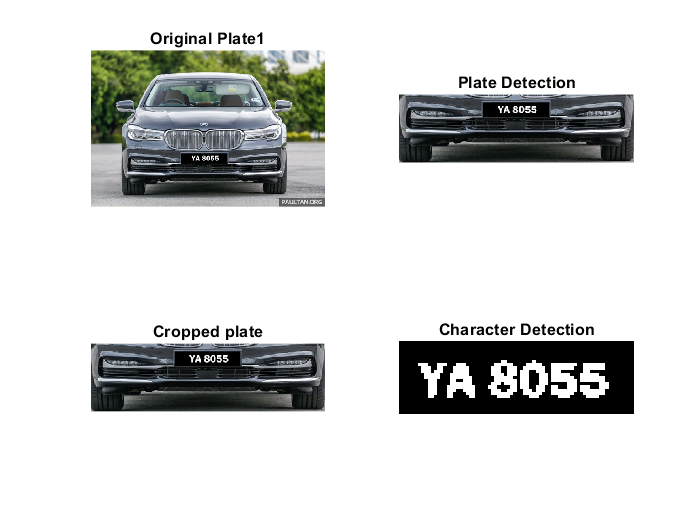

I = imread('C:\Users\issab\Documents\aMonash Units\Y3S1\aFIT3081 Image Processing\Assignment1\Car number plate images\Plate2.jpg');    % Read image
Igray = rgb2gray(I);            % Convert rgb image to grayscale
Ibin = imbinarize(Igray);       % Convert grayscale to binary image
Igray = medfilt2(Igray, [5 5]); % Perform median filtering with 5x5 neighbourhood
% Dilate grayscale image (remove unwanted noise etc...)
SE = strel('disk', 6); 
A = imdilate(Igray, SE);
B = imbinarize(A);
% Edge detection using Prewitt
C = edge(A, 'prewitt');
% Vertical and Horizontal dilation to retrieve lost linear gaps
HoriSE = ones(1,6);
VertSE = ones(6,1);
D = imdilate(C, VertSE);
E = imdilate(D, HoriSE);
% Fill gaps, clear borders and unwanted diagonal objects
F = imfill(E,  'holes');
F = imclearborder(F, 8);
% Find location of number plate -> largest rectangle area
P = regionprops(F, 'BoundingBox', 'Area', 'Image');
area = P.Area;
count = numel(P);
maxa = area;
boundingBox = P.BoundingBox;
for i=1:count
   if maxa<P(i).Area
       maxa=P(i).Area;
       boundingBox=P(i).BoundingBox;
   end
end
Plate = imcrop(I, boundingBox);
% Output results
figure,
subplot(2,2,1), imshow(I), title('Original Plate1');
subplot(2,2,2), imshow(Plate), title('Plate Detection');
I = Plate;
Igray = rgb2gray(I);            % Convert rgb to grayscale
Ibin = imbinarize(Igray);       % Binarize graysclae image
% Dilate grayscale image (remove unwanted noise etc...)
SE = strel('disk', 6); 
A = imdilate(Igray, SE);
% Perform sobel edge detection
E = edge(A, 'sobel');
% Vertical and horizontal dilation to retrieve lost linear gaps due to edge
% detection
HoriSE = ones(1,6);
VertSE = ones(6,1);
D = imdilate(E, VertSE);
F1 = imdilate(D, HoriSE);
% Fill gaps
F = imfill(F1, 'holes');
% Erode twice to perform thinning (allows original image to look natural)
SE = strel('disk', 2);
L = imerode(F, SE);
M = imerode(L, SE);
% Remove connected objects on border
% - remove diagonal connections
H = imclearborder(M, 4);
% Get boundingBox of greatest rectangle area -> Vehicle plate region
P = regionprops(H, 'BoundingBox', 'Area', 'Image');
area = P.Area;
count = numel(P);
maxa = area;
boundingBox = P.BoundingBox;
for i=1:count
   if maxa<P(i).Area
       maxa=P(i).Area;
       boundingBox=P(i).BoundingBox;
   end
end
% Crop out the detected plate region
Plate = imcrop(Ibin, boundingBox);
% Output images
subplot(2,2,3), imshow(I), title('Cropped plate');
subplot(2,2,4), imshow(Plate), title('Character Detection');

**Task 2 - Outline Extraction of Plate Characters**

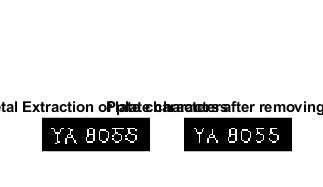

% skeletonization 
s = bwmorph (Plate, 'skel', 20); %repeating 20 times for optimal results
subplot(2,2,3); imshow (s, [] ); title("Skeletal Extraction of plate characters")

% removing spurs after skeletonization
s1 = bwmorph (s, 'spur', 1); %repeating 1 times for optimal results
subplot(2,2,4); imshow (s1, [] ); title("Plate characters after removing Spurs")

**Task 3 - Character Segmentation**

Plate 1

stats = regionprops(s1); %calculate structure array 
for index=1:length(stats)
if stats(index).Area > 100 && stats(index).Area < 300 && stats(index).BoundingBox(3)*stats(index).BoundingBox(4) < 10000 %condition to check the characters
      x = ceil(stats(index).BoundingBox(1))
      y = ceil(stats(index).BoundingBox(2))
      widthX = floor(stats(index).BoundingBox(3)-1)
      widthY = floor(stats(index).BoundingBox(4)-1)
      subimage(index) = {s1(y:y+widthY,x:x+widthX,:)}; 
      figure, imshow(subimage{index})
      end
end

Task 3 - Plate 2

x = 8

y = 8

widthX = 6

widthY = 9

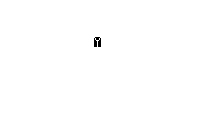

x = 17

y = 9

widthX = 6

widthY = 8

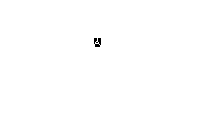

x = 31

y = 8

widthX = 5

widthY = 9

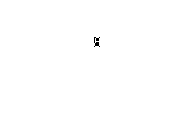

x = 40

y = 9

widthX = 6

widthY = 8

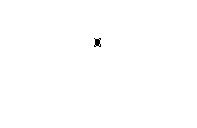

x = 50

y = 8

widthX = 5

widthY = 9

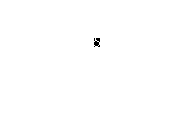

x = 59

y = 8

widthX = 6

widthY = 9

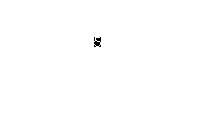

stats = regionprops(s1); %calculate structure array 
for index=1:length(stats)
if stats(index).Area > 0 && stats(index).BoundingBox(3)*stats(index).BoundingBox(4) < 10000 %condition to check the characters
      x = ceil(stats(index).BoundingBox(1))
      y = ceil(stats(index).BoundingBox(2))
      widthX = floor(stats(index).BoundingBox(3)-1)
      widthY = floor(stats(index).BoundingBox(4)-1)
      subimage(index) = {s1(y:y+widthY,x:x+widthX,:)}; 
      figure, imshow(subimage{index})
      end
end

Task 3 - Plate 3

stats = regionprops(s2); %calculate structure array 
for index=1:length(stats)
if stats(index).Area > 160 && stats(index).BoundingBox(3)*stats(index).BoundingBox(4) < 30000 %condition to check the characters
      x = ceil(stats(index).BoundingBox(1))
      y = ceil(stats(index).BoundingBox(2))
      widthX = floor(stats(index).BoundingBox(3)-1)
      widthY = floor(stats(index).BoundingBox(4)-1)
      subimage(index) = {s2(y:y+widthY,x:x+widthX,:)}; 
      figure, imshow(subimage{index})
      end
end

Task 3 - Plate 4

stats = regionprops(s1); %calculate structure array 
for index=1:length(stats)
if stats(index).Area > 0 && stats(index).Area < 50 && stats(index).BoundingBox(3)*stats(index).BoundingBox(4) < 30000 %condition to check the characters
      x = ceil(stats(index).BoundingBox(1))
      y = ceil(stats(index).BoundingBox(2))
      widthX = floor(stats(index).BoundingBox(3)-1)
      widthY = floor(stats(index).BoundingBox(4)-1)
      subimage(index) = {s1(y:y+widthY,x:x+widthX,:)}; 
      figure, imshow(subimage{index})
      end
end

## **Rear View**

- Plate 5,6

**Task 1 - Preprocessing: Detecting & Extracting Car Number Plate Area**

I = imread('C:\Program Files\MATLAB\R2020b\toolbox\images\imdata\Car number plate images\Plate6.jpg');    % Read image
Igray = rgb2gray(I);            % Convert rgb to grayscale
Ibin = imbinarize(Igray);       % Binarize graysclae image

% Dilate grayscale image (remove unwanted noise etc...)
SE = strel('disk', 6);  
A = imdilate(Igray, SE);

% Perform sobel edge detection
E = edge(A, 'sobel');

% Vertical and horizontal dilation to retrieve lost linear gaps due to edge
% detection
HoriSE = ones(1,6);
VertSE = ones(6,1);
D = imdilate(E, VertSE);
F1 = imdilate(D, HoriSE);

% Fill gaps
F = imfill(F1, 'holes');

% Erode twice to perform thinning (allows original image to look natural)
SE = strel('disk', 2);
L = imerode(F, SE);
M = imerode(L, SE);

% Remove connected objects on border
% - remove diagonal connections
H = imclearborder(M, 4);

% Get boundingBox of greatest rectangle area -> Vehicle plate region
P = regionprops(H, 'BoundingBox', 'Area', 'Image');
area = P.Area;
count = numel(P);
maxa = area;
boundingBox = P.BoundingBox;
for i=1:count
    if maxa<P(i).Area
        maxa=P(i).Area;
        boundingBox=P(i).BoundingBox;
    end
end

% Crop out the detected plate region
Plate = imcrop(Ibin, boundingBox);

% Output images
figure,
subplot(2,2,1), imshow(I), title('Original Plate6');
subplot(2,2,2), imshow(Plate), title('Plate Detection');

**Task 2 - Outline Extraction of Plate Characters**

% skeletonization 
s = bwmorph (Plate, 'skel', 20); %repeating 20 times for optimal results
subplot(2,2,3); imshow (s, [] ); title("Skeletal Extraction of plate characters");

% removing spurs after skeletonization
s1 = bwmorph (s, 'spur', 1); %repeating 1 times for optimal results
subplot(2,2,4); imshow (s1, [] ); title("Plate characters after removing Spurs");

**Task 3 - Character Segmentation **

stats = regionprops(s1); %calculate structure array 
for index=1:length(stats)
if stats(index).Area > 0 && stats(index).BoundingBox(3)*stats(index).BoundingBox(4) < 10000 %condition to check the characters
      x = ceil(stats(index).BoundingBox(1))
      y = ceil(stats(index).BoundingBox(2))
      widthX = floor(stats(index).BoundingBox(3)-1)
      widthY = floor(stats(index).BoundingBox(4)-1)
      subimage(index) = {s1(y:y+widthY,x:x+widthX,:)}; 
      figure, imshow(subimage{index})
      end
end

## **Diagonal Plate**

- Plate 7

**Task 1 - Preprocessing: Detecting & Extracting Car Number Plate Area**

I = imread('C:\Program Files\MATLAB\R2020b\toolbox\images\imdata\Car number plate images\Plate7.jpg');    % Read image
Igray = rgb2gray(I);            % Convert to grayscale
Ibin = imbinarize(Igray);       % Binarize grayscale image
Igray = medfilt2(Igray, [3 3]);

% Perform sobel edge detection
E = edge(Igray, 'sobel');

% Vertical and horizontal dilation to retrive lost linear gaps due to edge
% detection
SE1 = ones(6, 1);
D = imdilate(E, SE1);
SE2 = ones(1, 6);
F = imdilate(D, SE2);

% Fill gaps
G = imfill(F, 'holes');

% Remove connected objects on border
% - remove diagonal connections
H = imclearborder(G, 4);

% Structuring element of line
SE3 = strel('line', 100, 0);

% Perform erosion twice to retrieve the area of vehicle plate
J = imerode(H, SE3);
M = imerode(J, SE3);

% Find location of number plate -> largest rectangle area
P = regionprops(M, 'BoundingBox', 'Area', 'Image');
area = P.Area;
count = numel(P);
maxa = area;
boundingBox = P.BoundingBox;
for i=1:count
   if maxa<P(i).Area
       maxa=P(i).Area;
       boundingBox=P(i).BoundingBox;
   end
end

% Crop detected region of vehicle plate
Plate = imcrop(Ibin, boundingBox);

% Output results
figure,
subplot(2,2,1); imshow(I), title('Original Plate7');
subplot(2,2,2); imshow(Plate), title('Cropped Plate');

**Task 2 - Outline Extraction of Plate Characters**

% erosion
SE = [1 1 1; 1 1 1; 1 1 1];
OUT = imerode(Plate, SE);
figure,subplot(2,2,1); imshow(Plate); title("Cropped Number Plate")
subplot(2,2,2); imshow(OUT); title("Eroded Number Plate")

% skeletonization 
s = bwmorph (OUT, 'skel', 20); %repeating 20 times for optimal results
subplot(2,2,3); imshow (s, [] ); title("Skeletal Extraction of plate characters")

% removing spurs after skeletonization
s1 = bwmorph (s, 'spur', 5); %repeating 5 times for optimal results
subplot(2,2,4); imshow (s1, [] ); title("Plate characters after removing Spurs")

**Task 3 - Character Segmentation**

stats = regionprops(s1); %calculate structure array 
for index=1:length(stats)
if stats(index).Area > 0 && stats(index).BoundingBox(3)*stats(index).BoundingBox(4) < 10000 %condition to check the characters
      x = ceil(stats(index).BoundingBox(1))
      y = ceil(stats(index).BoundingBox(2))
      widthX = floor(stats(index).BoundingBox(3)-1)
      widthY = floor(stats(index).BoundingBox(4)-1)
      subimage(index) = {s1(y:y+widthY,x:x+widthX,:)}; 
      figure, imshow(subimage{index})
      end
end

## **Plate Only**

- Plate 8, 9

- difference: median filtering for noise & canny edge detection

- - remove everything outside of the box because we already know that the image only consists of the license plate

- difference: erosion first then clearborder

- - due to canny edge, we want to perform thinning first then we use clearborder() to detect unwanted diagonal connections

**Task 1 - Preprocessing: Detecting & Extracting Car Number Plate Area**

I = imread('C:\Program Files\MATLAB\R2020b\toolbox\images\imdata\Car number plate images\Plate9.jpg');    % Read image
I = imresize(I, [480 640]);     % Resize image
Igray = rgb2gray(I);            % Convert rgb image to grayscale
Igray = medfilt2(Igray, [3 3]); % Median filtering to remove noise
Ibin = imbinarize(Igray);       % Binarize grayscale image

% Edge detection using Canny with threshold
E = edge(Igray, 'canny', 0.3);

% Vertical and Horizontal dilation to retrieve lost linear gaps
HoriSE = ones(1,6);
VertSE = ones(6,1);
D = imdilate(E, VertSE);
F1 = imdilate(D, HoriSE);

% Fill gaps
F = imfill(F1, 'holes');

% Perform erosion twice to retrieve the area of vehicle plate
SE = strel('disk', 2);
L = imerode(F, SE);
M = imerode(L, SE);

% Remove connected objects on border
% - remove diagonal connections
H = imclearborder(M, 4);

% Find location of number plate -> largest rectangle area
P = regionprops(H, 'BoundingBox', 'Area', 'Image');
area = P.Area;
count = numel(P);
maxa = area;
boundingBox = P.BoundingBox;
for i=1:count
   if maxa<P(i).Area
       maxa=P(i).Area;
       boundingBox=P(i).BoundingBox;
   end
end

% Crop detected region of vehicle plate
Plate = imcrop(Ibin, boundingBox);

% Output results
figure,
subplot(1,2,1), imshow(I); title('Original Plate9');
subplot(1,2,2), imshow(Plate); title('Plate Detection');

**Task 2 - Outline Extraction of Plate Characters**

% erosion
SE = [1 1 1; 1 1 1; 1 1 1];
OUT = imerode(Plate, SE);
figure,subplot(2,2,1); imshow(Plate); title("Cropped Number Plate")
subplot(2,2,2); imshow(OUT); title("Eroded Number Plate")

% skeletonization 
s = bwmorph (OUT, 'skel', 20); %repeating 20 times for optimal results
subplot(2,2,3); imshow (s, [] ); title("Skeletal Extraction of plate characters")

% removing spurs after skeletonization
s1 = bwmorph (s, 'spur', 5); %repeating 5 times for optimal results
subplot(2,2,4); imshow (s1, [] ); title("Plate characters after removing Spurs")

s2 = imclearborder(s1,8);
figure,
subplot(2,2,3); imshow(s2,[]); title('Removed border');

**Task 3 - Character Segmentation**

Plate 8

stats = regionprops(s2); %calculate structure array 
for index=1:length(stats)
if stats(index).Area > 20 && stats(index).Area < 120 && stats(index).BoundingBox(3)*stats(index).BoundingBox(4) < 10000 %condition to check the characters
      x = ceil(stats(index).BoundingBox(1))
      y = ceil(stats(index).BoundingBox(2))
      widthX = floor(stats(index).BoundingBox(3)-1)
      widthY = floor(stats(index).BoundingBox(4)-1)
      subimage(index) = {s2(y:y+widthY,x:x+widthX,:)}; 
      figure, imshow(subimage{index})
      end
end

**Task 3 - Character Segmentation**

Plate 9

stats = regionprops(s2); %calculate structure array 
for index=1:length(stats)
if stats(index).Area > 50 && stats(index).Area < 200 && stats(index).BoundingBox(3)*stats(index).BoundingBox(4) < 10000 %condition to check the characters
      x = ceil(stats(index).BoundingBox(1))
      y = ceil(stats(index).BoundingBox(2))
      widthX = floor(stats(index).BoundingBox(3)-1)
      widthY = floor(stats(index).BoundingBox(4)-1)
      subimage(index) = {s2(y:y+widthY,x:x+widthX,:)}; 
      figure, imshow(subimage{index})
      end
end